clc,clear

load sysid02.mat

sys = idss(drss(4,1,1)); sys.D=zeros(1,1); % skapar en random 4th order state-space model med två input två output, D=0
z = iddata(y,u) % skapar data objekt

z =

Time domain data set with 1000 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        



% Estimera en 4th order state space modell
ms = n4sid(z,4)

ms =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4
   x1    0.5239    -0.819  -0.02934   0.05646
   x2    0.8417    0.5317  -0.07998   0.07717
   x3   0.06273  -0.06411   -0.4176   -0.8797
   x4    0.1227  -0.02152    0.9033   -0.3838
 
  B = 
             u1
   x1  -0.00733
   x2  0.002811
   x3  0.006577
   x4  0.004705
 
  C = 
           x1      x2      x3      x4
   y1  -239.5    11.1  -142.3  -42.72
 
  D = 
       u1
   y1   0
 
  K = 
               y1
   x1  -0.0003835
   x2  -0.0002903
   x3   0.0006342
   x4  -0.0008454
 
Sample time: 1 seconds
  
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 28
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using 

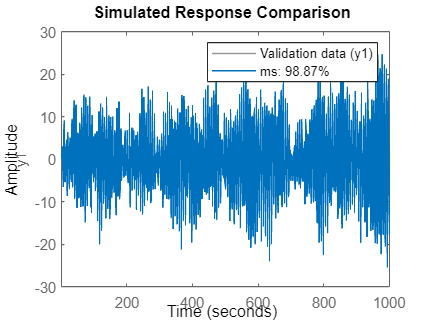

compare(iddata(y,u),ms)

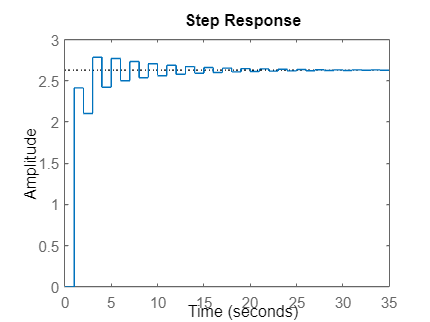

stepplot(sys)